# Plots to simplify the results for Context-Specfic models

## Load the data

Go through the xlsx results and separate them based on the mean and standard deviation for all the models and the standard deviation 

% Load the Excel file
filename = 'data_2_plot_Same75.xlsx';
data = readtable(filename);

% Define the number of rows per segment
rows_per_segment = 6;

% Get the column names
column_names = data.Properties.VariableNames;

% Initialize a table for the results
results = table;

% Iterate over the dataframe in blocks of 6 rows
for i = 1:rows_per_segment:height(data)
    % Determine the final index of the segment
    end_row = min(i + rows_per_segment - 1, height(data));
    
    % Extract the segment
    segment = data(i:end_row, :);
    
    % Calculate the mean and standard deviation of the segment
    mean_segment = mean(segment{:, 2:end}, 'omitnan');
    std_segment = std(segment{:, 2:end}, 'omitnan');
    
    % Extract the method and threshold from the first element of the segment
    name_parts = split(data{i, 1}{1}, '_');
    method = name_parts{1};
    threshold = name_parts{end};
    
    % Create names for the result rows
    mean_row_name = sprintf('%s_Mean_%s', method, threshold);
    std_row_name = sprintf('%s_ST_%s', method, threshold);
    
    % Add the means to the results table
    new_row = array2table(mean_segment, 'VariableNames', column_names(2:end));
    new_row.Properties.RowNames = {mean_row_name};
    results = [results; new_row];
    
    % Add the standard deviations to the results table
    new_row = array2table(std_segment, 'VariableNames', column_names(2:end));
    new_row.Properties.RowNames = {std_row_name};
    results = [results; new_row];
end

% Save the results to a new Excel file
output_filename = 'Final_results_statistics.xlsx';
writetable(results, output_filename, 'WriteRowNames', true);

% Load the Excel file with the results
data = readtable(output_filename, 'ReadRowNames', true);

## Define the points on the x-axis

x = categorical({'Global thresholding', 'LocalT2', 'LocalGini', 'StanDep'});

% Function to check the existence of a row in the table
function exists = check_row_exists(data, row_name)
    exists = ismember(row_name, data.Properties.RowNames);
end

% Function to extract data and generate the plots
function [mean_values, std_values] = extract_data(data, column_name, row_prefix)
    mean_values = [];
    std_values = [];
    for prefix = ["G", "LT2", "LG", "SD"]
        mean_row = sprintf('%s_Mean_%s', row_prefix, prefix);
        std_row = sprintf('%s_ST_%s', row_prefix, prefix);
        if check_row_exists(data, mean_row) && check_row_exists(data, std_row)
            mean_values = [mean_values; data{mean_row, {column_name}}];
            std_values = [std_values; data{std_row, {column_name}}];
        else
            mean_values = [mean_values; NaN];
            std_values = [std_values; NaN];
        end
    end
end

## Create the figure

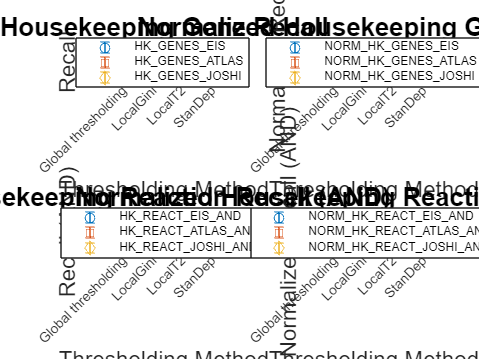

figure;

titleFontSize = 16;
labelFontSize = 14;
legendFontSize = 12;

% Subplot 1: Housekeeping Gene Recall
subplot(2,2,1);
hold on;
ylim([0.5 1]);
[mean_values, std_values] = extract_data(data, 'HK_GENES_EIS', 'FASTCORE');
errorbar(x, mean_values, std_values, 'o', 'DisplayName', 'HK\_GENES\_EIS');
[mean_values, std_values] = extract_data(data, 'HK_GENES_ATLAS', 'FASTCORE');
errorbar(x, mean_values, std_values, 's', 'DisplayName', 'HK\_GENES\_ATLAS');
[mean_values, std_values] = extract_data(data, 'HK_GENES_JOSHI', 'FASTCORE');
errorbar(x, mean_values, std_values, 'd', 'DisplayName', 'HK\_GENES\_JOSHI');
title('Housekeeping Gene Recall', 'FontSize', titleFontSize);
xlabel('Thresholding Method', 'FontSize', labelFontSize);
ylabel('Recall', 'FontSize', labelFontSize);
legend('Location', 'best');
grid on;
hold off;

% Subplot 2: Normalized Housekeeping Gene Recall
subplot(2,2,2);
hold on;
%ylim([0.35 0.5]);
[mean_values, std_values] = extract_data(data, 'NORM_HK_GENES_EIS', 'FASTCORE');
errorbar(x, mean_values, std_values, 'o', 'DisplayName', 'NORM\_HK\_GENES\_EIS');
[mean_values, std_values] = extract_data(data, 'NORM_HK_GENES_ATLAS', 'FASTCORE');
errorbar(x, mean_values, std_values, 's', 'DisplayName', 'NORM\_HK\_GENES\_ATLAS');
[mean_values, std_values] = extract_data(data, 'NORM_HK_GENES_JOSHI', 'FASTCORE');
errorbar(x, mean_values, std_values, 'd', 'DisplayName', 'NORM\_HK\_GENES\_JOSHI');
title('Normalized Housekeeping Gene Recall', 'FontSize', titleFontSize);
xlabel('Thresholding Method', 'FontSize', labelFontSize);
ylabel('Normalized Recall', 'FontSize', labelFontSize);
legend('Location', 'best');
grid on;
hold off;

% Subplot 3: Housekeeping Reaction Recall (AND)
subplot(2,2,3);
hold on;
ylim([0.5 1]);
[mean_values, std_values] = extract_data(data, 'HK_REACT_EIS_AND', 'FASTCORE');
errorbar(x, mean_values, std_values, 'o', 'DisplayName', 'HK\_REACT\_EIS\_AND');
[mean_values, std_values] = extract_data(data, 'HK_REACT_ATLAS_AND', 'FASTCORE');
errorbar(x, mean_values, std_values, 's', 'DisplayName', 'HK\_REACT\_ATLAS\_AND');
[mean_values, std_values] = extract_data(data, 'HK_REACT_JOSHI_AND', 'FASTCORE');
errorbar(x, mean_values, std_values, 'd', 'DisplayName', 'HK\_REACT\_JOSHI\_AND');
title('Housekeeping Reaction Recall (AND)', 'FontSize', titleFontSize);
xlabel('Thresholding Method', 'FontSize', labelFontSize);
ylabel('Recall (AND)', 'FontSize', labelFontSize);
legend('Location', 'best');
grid on;
hold off;

% Subplot 4: Normalized Housekeeping Reaction Recall (AND)
subplot(2,2,4);
hold on;
%ylim([0.35 0.5]);
[mean_values, std_values] = extract_data(data, 'NORM_HK_REACT_EIS_AND', 'FASTCORE');
errorbar(x, mean_values, std_values, 'o', 'DisplayName', 'NORM\_HK\_REACT\_EIS\_AND');
[mean_values, std_values] = extract_data(data, 'NORM_HK_REACT_ATLAS_AND', 'FASTCORE');
errorbar(x, mean_values, std_values, 's', 'DisplayName', 'NORM\_HK\_REACT\_ATLAS\_AND');
[mean_values, std_values] = extract_data(data, 'NORM_HK_REACT_JOSHI_AND', 'FASTCORE');
errorbar(x, mean_values, std_values, 'd', 'DisplayName', 'NORM\_HK\_REACT\_JOSHI\_AND');
title('Normalized Housekeeping Reaction Recall (AND)', 'FontSize', titleFontSize);
xlabel('Thresholding Method', 'FontSize', labelFontSize);
ylabel('Normalized Recall (AND)', 'FontSize', labelFontSize);
legend('Location', 'best');
grid on;
hold off;

% Save the figure to a PNG file
output_filename = 'Combined_Plots_Same75.png';
saveas(gcf, output_filename);